Quick interactive tutorial on using Daubechies' wavelets for eigenvalue problems. **[Notebook 1 of 2]**

- Press Ctrl + Enter to run sections of code. 

- F5 to run the whole notebook.

- F1 with cursor next to any function for its MATLAB documentation.

- Look at the *Workspace* tab for inspecting variable dimensions/structure. 

Assumes some familiarity with linear algebra, fourier analysis, and .mlx notebooks.

Complements discussion in *doi:10.1007/s00601-013-0735-9* with MATLAB how-to.

Daubechies Wavelets - (families of) set of orthonormal functions. MATLAB will furnish them for you like so: 

[w,x] = wpfun('db3',1,5); %inspect w, x in the workspace tab!

- *w(1, :) *holds $\phi \left(x\right)\equiv$ $s_0^0 $

- *w(2, :) *holds $\psi \left(x\right)\equiv$ $w_0^0$

- *5* specifies precision.

- db**3** sets **K** **= 3 **which means $\int_{-\infty}^{\infty} x^pw(x)dx = 0 $ $\forall $ $0 \leq p \leq K$ and $w(x) \in db3$

Plotting $s_0^0 $ and $w_0^0$.

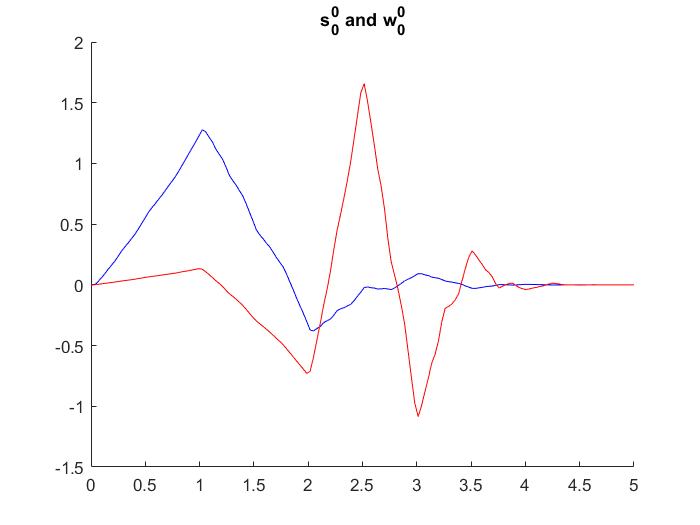

figure(1); clf; 
hold on

plot(x, w(1,:), 'blue'); 
plot(x, w(2,:), 'red'); 
title('s^0_0 and w^0_0'); 

hold off

- Both wavelets are non-zero only in $[0, 2K-1]$, here $[0, 5]$*.*

- K = 3 wavelets are singly differentiable.

- K = 5 wavelets are doubly differentiable.

- Look at their orthonormality properties in references.

- We need their scaled/translated copies for our purpose.

Plotting $w_0^0$ and $w_1^1 $.

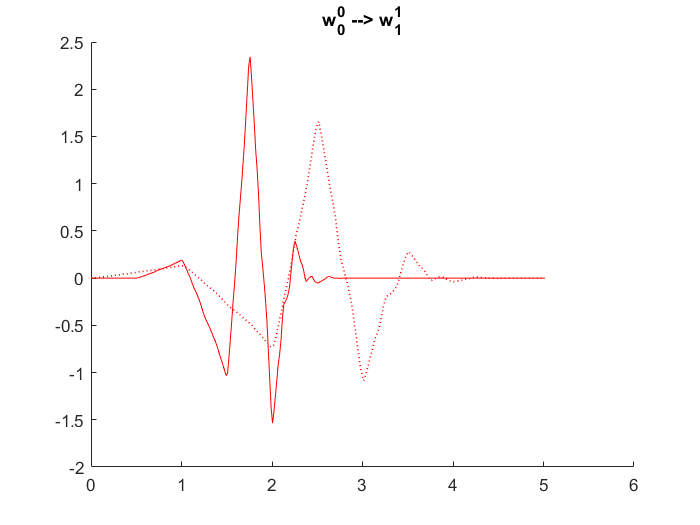

figure(2); clf; 
hold on

[w11, x11] = DT(w(2,:), x,1,1);
plot(x11, w11, 'red'); 
plot(x, w(2,:), 'red', 'LineStyle',":", "LineWidth",1);
title('w_0^0 --> w_1^1');

hold off 

- At k = 1, n = 1, support changes to $[0.5, 3]$

- $w_1^1 $ is orthonormal to $w_0^0$

- wavelets at different resolutions (different k) are orthonormal to each other; this is what makes multiresolution fourier-like analysis possible

Calculating integrals

- a = $\int_{-\infty}^{\infty} w_0^0(x)dx = 0 $

- b = $\int_{-\infty}^{\infty} s_0^0 (x)\cdot w_0^0(x)dx = 0 \equiv \langle s_0^0 | w_0^0\rangle$

- c = $\langle w_0^0 | x^2|  w_0^0\rangle$

fprintf("Integrals");

Integrals

fprintf("a = %f", trapz(w(2,:)) * x(2));

a = -0.000000

fprintf("b = %f", trapz(w(1,:) .* w(2,:)) * x(2));

b = -0.014629

fprintf("c = %f", trapz(w(2,:) .* x.^2 .* w(2,:)) * x(2));

c = 6.398836

trapz(f(x) * g(x)) * $\Delta$x performs simple numerical integration. 

Utility functions to scale, translate, and differentiate. 

function [DTw, DTx] = DT(w,x,k,n)
    %changes w00 to wkn
    %keep n <= (2K - 1)(2^k - 1)
    DTw = w;
    DTx = x+n;
    
    DTw = 2^(k/2)*DTw;
    DTx = DTx/(2^k);
    
    newxstep = DTx(2) - DTx(1);
    Lpad = round(DTx(1) / newxstep);
    
    DTx = wextend('1', 'asymw', DTx, length(DTx)*(2^k - 1), 'r');
    
    DTw = [DTw , zeros(1,(length(DTx) - length(DTw)))];
    DTw = circshift(DTw, Lpad); DTw(1:Lpad) = zeros(1, Lpad);   
    DTx = wextend('1', 'asymw', DTx, Lpad, 'l');
    
    DTx = DTx(1:length(DTw));
    
end

function [wd, xd] = singlediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    xd = x;
end

function [wdd, xdd] = doublediff(w, x)
    wd = gradient(w)/(x(2) - x(1));
    wdd = gradient(wd)/(x(2) - x(1));
    xdd = x;
end
